Allan Variance Test: Acceleration Data Analysis 

Author: Michael Noyce 

**Description**: 

This program performs an Allan Variance Analysis of intertial data. Please run the AllanVarianceTestDataCapture.mlx program first to introduce the correct variables into your workspace. Largely Based on: [https://www.mathworks.com/help/fusion/ug/inertial-sensor-noise-analysis-using-allan-variance.html](https://www.mathworks.com/help/fusion/ug/inertial-sensor-noise-analysis-using-allan-variance.html) 

Note: As 3 acceleration Axes are calculated and simulations are performed with the calculated values, this program takes a while! Start it, make a cup of coffee and come back :) 

helperAllanVarianceExample.m is needed in the same folder to run simulations with the calculated noise characteristics.  

%Define Variables
t0 = 1/fs; %sample period
accX = accelTimeSeries(:, 2); 
accY = accelTimeSeries(:, 3);
accZ = accelTimeSeries(:, 4);

%Integrate gyroscope measurements to find orientation 
xAxisIntegrated = cumsum(accX, 1)*t0; 
yAxisIntegrated = cumsum(accY, 1)*t0; 
zAxisIntegrated = cumsum(accZ, 1)*t0; 

%Simulation Commands (automatically set to false)
simulateXaxis = false;
simulateYaxis = false;
simulateZaxis = false;



**Gyroscope Allan Variance Calculation: X axis **

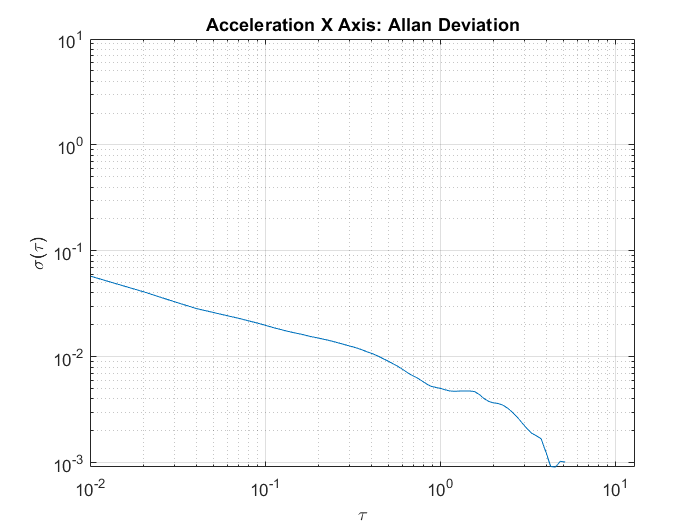

%Allan Variance Calculation: X axis
maxNumM = 100;
L = size(xAxisIntegrated, 1);
maxM = 2.^floor(log2(L/2));
m = logspace(log10(1), log10(maxM), maxNumM).';
m = ceil(m); % m must be an integer.
m = unique(m); % Remove duplicates.

tau = m*t0;

avar = zeros(numel(m), 1);
for i = 1:numel(m)
    mi = m(i);
    avar(i,:) = sum((xAxisIntegrated(1+2*mi:L) - 2*xAxisIntegrated(1+mi:L-mi) + xAxisIntegrated(1:L-2*mi)).^2, 1);
end

avar = avar ./ (2*tau.^2 .* (L - 2*m));

adev = sqrt(avar);

figure
loglog(tau, adev)
title('Acceleration X Axis: Allan Deviation')
xlabel('\tau');
ylabel('\sigma(\tau)')
grid on
axis equal


%Angle Random Walk Calculation 

% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slope = -0.5;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i);

% Determine the angle random walk coefficient from the line.
logN = slope*log(1) + b;
N = 10^logN

N = 0.0057

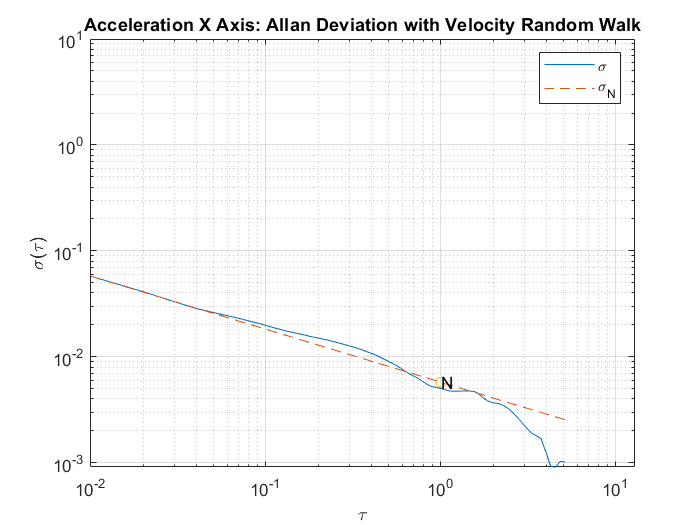


% Plot the results.
tauN = 1;
lineN = N ./ sqrt(tau);
figure
loglog(tau, adev, tau, lineN, '--', tauN, N, 'o')
title('Acceleration X Axis: Allan Deviation with Velocity Random Walk')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_N')
text(tauN, N, 'N')
grid on
axis equal


%Rate Random Walk Calulation

% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slope = 0.5;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i);

% Determine the rate random walk coefficient from the line.
logK = slope*log10(3) + b;
K = 10^logK

K = 0.0074

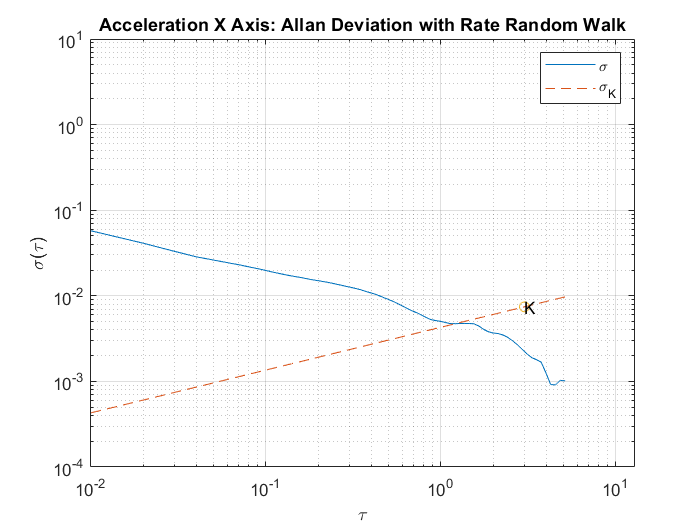


% Plot the results.
tauK = 3;
lineK = K .* sqrt(tau/3);
figure
loglog(tau, adev, tau, lineK, '--', tauK, K, 'o')
title('Acceleration X Axis: Allan Deviation with Rate Random Walk')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_K')
text(tauK, K, 'K')
grid on
axis equal


%Bias Instability Calculation 

% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slope = 0;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i);

% Determine the bias instability coefficient from the line.
scfB = sqrt(2*log(2)/pi);
logB = b - log10(scfB);
B = 10^logB

B = 0.0072

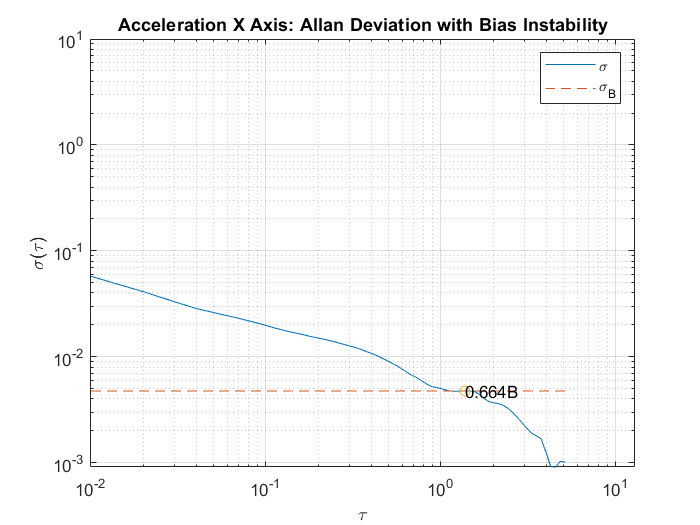


% Plot the results.
tauB = tau(i);
lineB = B * scfB * ones(size(tau));
figure
loglog(tau, adev, tau, lineB, '--', tauB, scfB*B, 'o')
title('Acceleration X Axis: Allan Deviation with Bias Instability')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_B')
text(tauB, scfB*B, '0.664B')
grid on
axis equal

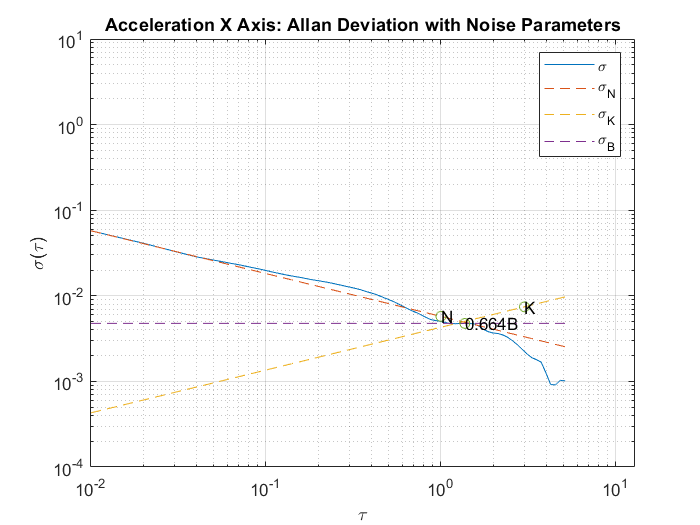


tauParams = [tauN, tauK, tauB];
params = [N, K, scfB*B];
figure
loglog(tau, adev, tau, [lineN, lineK, lineB], '--', ...
    tauParams, params, 'o')
title('Acceleration X Axis: Allan Deviation with Noise Parameters')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_N', '\sigma_K', '\sigma_B')
text(tauParams, params, {'N', 'K', '0.664B'})
grid on
axis equal


%Simulate Output with Allan Variance Parameters
%Make sure helperAllanVarianceExample is in the workspace 
if simulateXaxis == true
    gyro = gyroparams('NoiseDensity', N, 'RandomWalk', K, ...
        'BiasInstability', B);
    omegaSim = helperAllanVarianceExample(L, fs, gyro);

    [avarSim, tauSim] = allanvar(omegaSim, 'octave', fs);
    adevSim = sqrt(avarSim);
    adevSim = mean(adevSim, 2); % Use the mean of the simulations.

    figure
    loglog(tau, adev, tauSim, adevSim, '--')
    title('Acceleration X Axis: Allan Deviation of HW and Simulation')
    xlabel('\tau');
    ylabel('\sigma(\tau)')
    legend('HW', 'SIM')
    grid on
    axis equal
end 


**Allan Variance Calculation: Y axis **

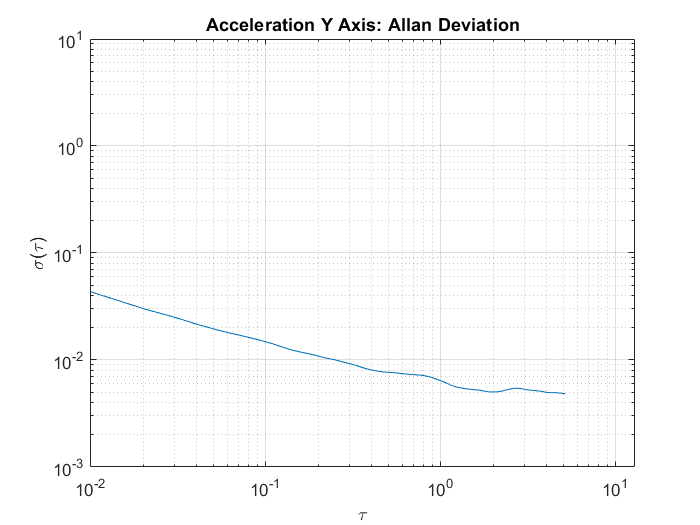

%Allan Variance Calculation: Y axis
maxNumM = 100;
L = size(yAxisIntegrated, 1);
maxM = 2.^floor(log2(L/2));
m = logspace(log10(1), log10(maxM), maxNumM).';
m = ceil(m); % m must be an integer.
m = unique(m); % Remove duplicates.

tau = m*t0;

avar = zeros(numel(m), 1);
for i = 1:numel(m)
    mi = m(i);
    avar(i,:) = sum((yAxisIntegrated(1+2*mi:L) - 2*yAxisIntegrated(1+mi:L-mi) + yAxisIntegrated(1:L-2*mi)).^2, 1);
end

avar = avar ./ (2*tau.^2 .* (L - 2*m));

adev = sqrt(avar);

figure
loglog(tau, adev)
title('Acceleration Y Axis: Allan Deviation')
xlabel('\tau');
ylabel('\sigma(\tau)')
grid on
axis equal


%Angle Random Walk Calculation 

% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slope = -0.5;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i);

% Determine the angle random walk coefficient from the line.
logN = slope*log(1) + b;
N = 10^logN

N = 0.0046

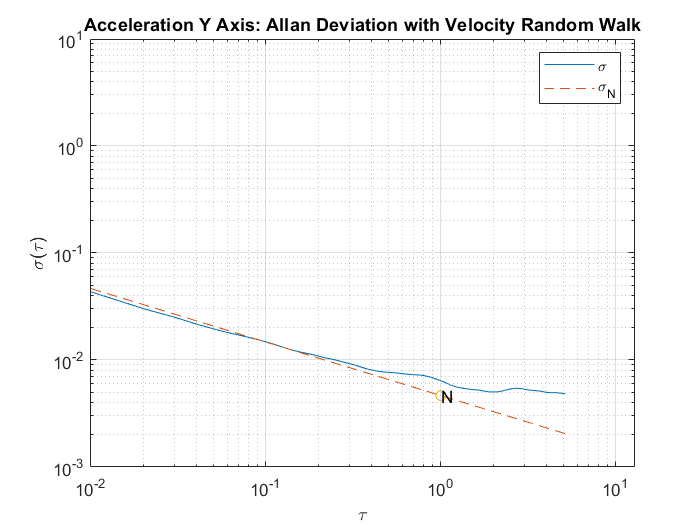


% Plot the results.
tauN = 1;
lineN = N ./ sqrt(tau);
figure
loglog(tau, adev, tau, lineN, '--', tauN, N, 'o')
title('Acceleration Y Axis: Allan Deviation with Velocity Random Walk')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_N')
text(tauN, N, 'N')
grid on
axis equal


%Rate Random Walk Calulation

% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slope = 0.5;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i);

% Determine the rate random walk coefficient from the line.
logK = slope*log10(3) + b;
K = 10^logK

K = 0.0059

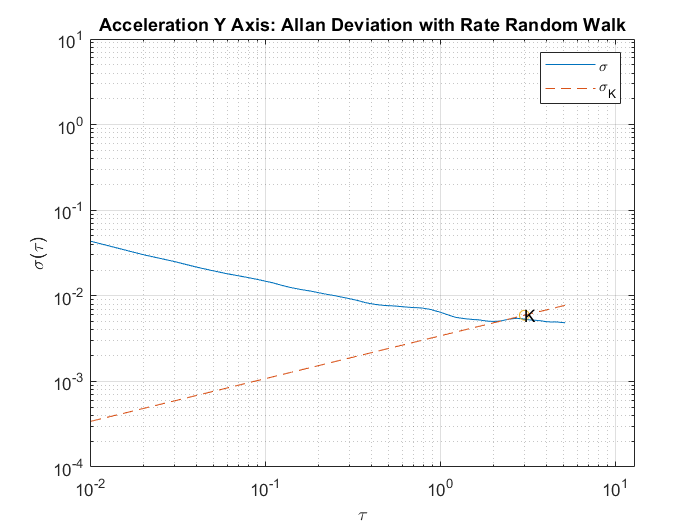


% Plot the results.
tauK = 3;
lineK = K .* sqrt(tau/3);
figure
loglog(tau, adev, tau, lineK, '--', tauK, K, 'o')
title('Acceleration Y Axis: Allan Deviation with Rate Random Walk')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_K')
text(tauK, K, 'K')
grid on
axis equal


%Bias Instability Calculation 

% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slope = 0;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i);

% Determine the bias instability coefficient from the line.
scfB = sqrt(2*log(2)/pi);
logB = b - log10(scfB);
B = 10^logB

B = 0.0074

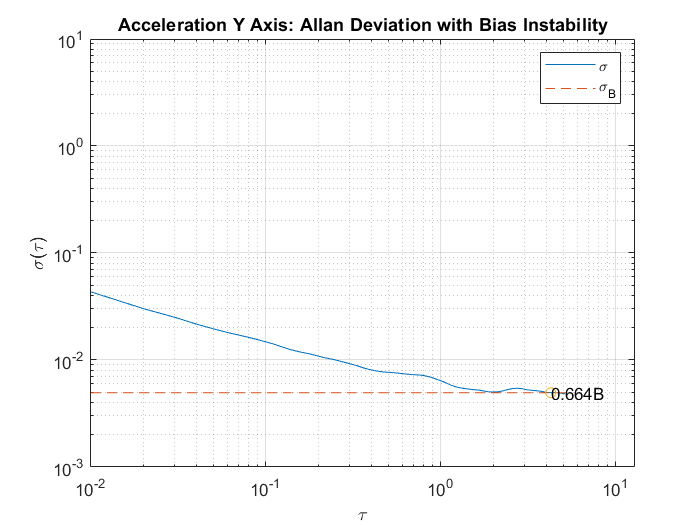


% Plot the results.
tauB = tau(i);
lineB = B * scfB * ones(size(tau));
figure
loglog(tau, adev, tau, lineB, '--', tauB, scfB*B, 'o')
title('Acceleration Y Axis: Allan Deviation with Bias Instability')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_B')
text(tauB, scfB*B, '0.664B')
grid on
axis equal

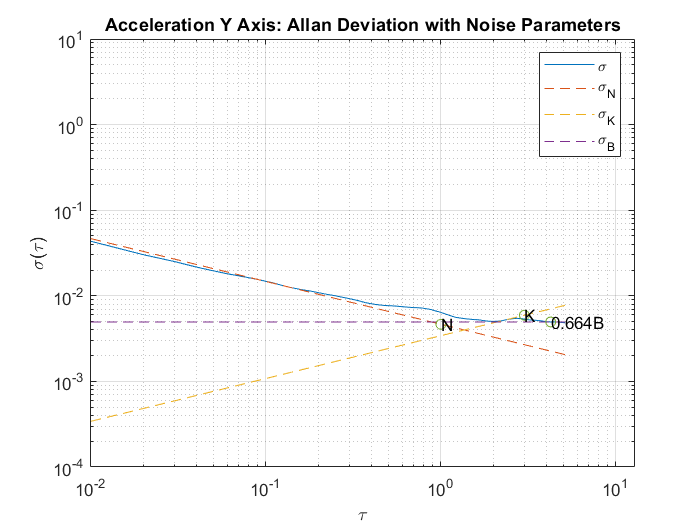


tauParams = [tauN, tauK, tauB];
params = [N, K, scfB*B];
figure
loglog(tau, adev, tau, [lineN, lineK, lineB], '--', ...
    tauParams, params, 'o')
title('Acceleration Y Axis: Allan Deviation with Noise Parameters')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_N', '\sigma_K', '\sigma_B')
text(tauParams, params, {'N', 'K', '0.664B'})
grid on
axis equal


%Simulate Output with Allan Variance Parameters
%Make sure helperAllanVarianceExample is in the workspace 
if simulateYaxis == true
    gyro = gyroparams('NoiseDensity', N, 'RandomWalk', K, ...
        'BiasInstability', B);
    omegaSim = helperAllanVarianceExample(L, fs, gyro);

    [avarSim, tauSim] = allanvar(omegaSim, 'octave', fs);
    adevSim = sqrt(avarSim);
    adevSim = mean(adevSim, 2); % Use the mean of the simulations.

    figure
    loglog(tau, adev, tauSim, adevSim, '--')
    title('Acceleration Y Axis: Allan Deviation of HW and Simulation')
    xlabel('\tau');
    ylabel('\sigma(\tau)')
    legend('HW', 'SIM')
    grid on
    axis equal
end 


**Allan Variance Calculation: Z axis **

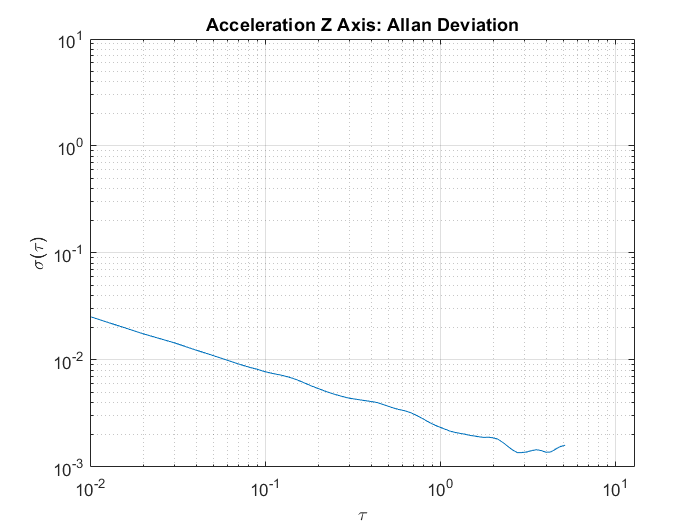

%Allan Variance Calculation: Z axis
maxNumM = 100;
L = size(zAxisIntegrated, 1);
maxM = 2.^floor(log2(L/2));
m = logspace(log10(1), log10(maxM), maxNumM).';
m = ceil(m); % m must be an integer.
m = unique(m); % Remove duplicates.

tau = m*t0;

avar = zeros(numel(m), 1);
for i = 1:numel(m)
    mi = m(i);
    avar(i,:) = sum((zAxisIntegrated(1+2*mi:L) - 2*zAxisIntegrated(1+mi:L-mi) + zAxisIntegrated(1:L-2*mi)).^2, 1);
end

avar = avar ./ (2*tau.^2 .* (L - 2*m));

adev = sqrt(avar);

figure
loglog(tau, adev)
title('Acceleration Z Axis: Allan Deviation')
xlabel('\tau');
ylabel('\sigma(\tau)')
grid on
axis equal


%Angle Random Walk Calculation 

% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slope = -0.5;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i);

% Determine the angle random walk coefficient from the line.
logN = slope*log(1) + b;
N = 10^logN

N = 0.0024

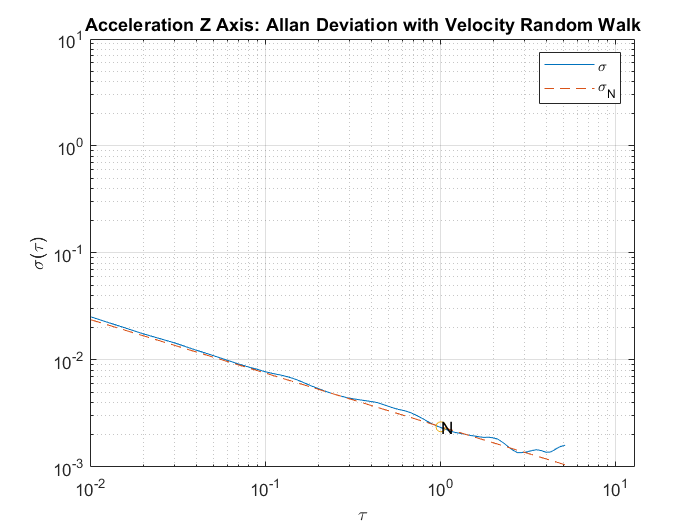


% Plot the results.
tauN = 1;
lineN = N ./ sqrt(tau);
figure
loglog(tau, adev, tau, lineN, '--', tauN, N, 'o')
title('Acceleration Z Axis: Allan Deviation with Velocity Random Walk')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_N')
text(tauN, N, 'N')
grid on
axis equal


%Rate Random Walk Calulation

% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slope = 0.5;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i);

% Determine the rate random walk coefficient from the line.
logK = slope*log10(3) + b;
K = 10^logK

K = 0.0012

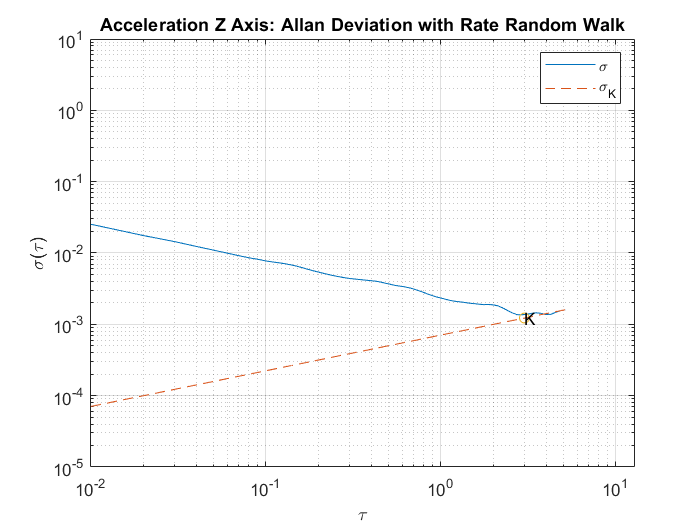


% Plot the results.
tauK = 3;
lineK = K .* sqrt(tau/3);
figure
loglog(tau, adev, tau, lineK, '--', tauK, K, 'o')
title('Acceleration Z Axis: Allan Deviation with Rate Random Walk')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_K')
text(tauK, K, 'K')
grid on
axis equal


%Bias Instability Calculation 

% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slope = 0;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i);

% Determine the bias instability coefficient from the line.
scfB = sqrt(2*log(2)/pi);
logB = b - log10(scfB);
B = 10^logB

B = 0.0021

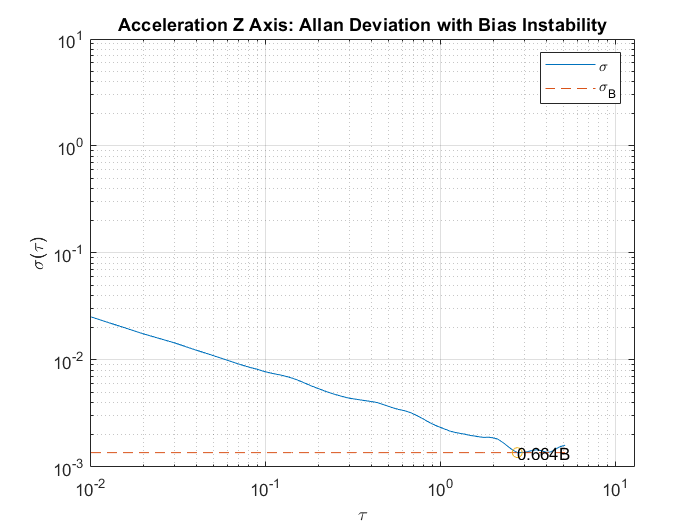


% Plot the results.
tauB = tau(i);
lineB = B * scfB * ones(size(tau));
figure
loglog(tau, adev, tau, lineB, '--', tauB, scfB*B, 'o')
title('Acceleration Z Axis: Allan Deviation with Bias Instability')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_B')
text(tauB, scfB*B, '0.664B')
grid on
axis equal

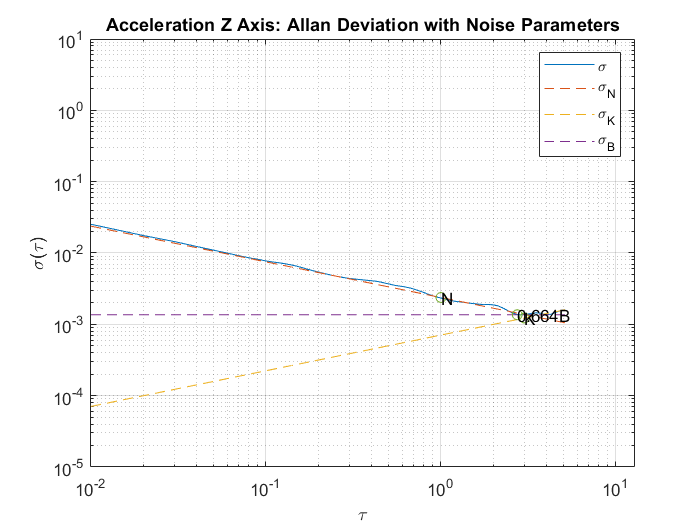


tauParams = [tauN, tauK, tauB];
params = [N, K, scfB*B];
figure
loglog(tau, adev, tau, [lineN, lineK, lineB], '--', ...
    tauParams, params, 'o')
title('Acceleration Z Axis: Allan Deviation with Noise Parameters')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_N', '\sigma_K', '\sigma_B')
text(tauParams, params, {'N', 'K', '0.664B'})
grid on
axis equal


%Simulate Output with Allan Variance Parameters
%Make sure helperAllanVarianceExample is in the workspace 
if simulateZaxis == true 
    gyro = gyroparams('NoiseDensity', N, 'RandomWalk', K, ...
        'BiasInstability', B);
    omegaSim = helperAllanVarianceExample(L, fs, gyro);

    [avarSim, tauSim] = allanvar(omegaSim, 'octave', fs);
    adevSim = sqrt(avarSim);
    adevSim = mean(adevSim, 2); % Use the mean of the simulations.

    figure
    loglog(tau, adev, tauSim, adevSim, '--')
    title('Acceleration Z Axis: Allan Deviation of HW and Simulation')
    xlabel('\tau');
    ylabel('\sigma(\tau)')
    legend('HW', 'SIM')
    grid on
    axis equal
end